 
robot = 
 
6-DOF Robot:: 7 axis, RRRRRRR, stdDH, slowRNE                    
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|    3.14159|          0|
|  2|         q2|      -0.45|       0.15|     1.5708|          0|
|  3|         q3|          0|       0.59|    3.14159|    -1.5708|
|  4|         q4|          0|       0.13|    -1.5708|     1.5708|
|  5|         q5|    -0.6471|          0|    -1.5708|          0|
|  6|         q6|          0|          0|     1.5708|          0|
|  7|         q7|     -0.095|          0|    3.14159|    3.14159|
+---+-----------+-----------+-----------+-----------+-----------+
 


Jacobian Matrix (Base Frame):


   -0.0000   -0.0000    0.5113    0.0787    0.0000    0.0950         0
    0.7868   -0.7868   -0.0000    0.0000    0.0849   -0.0000         0
         0    0.0000   -0.6368    0.6368   -0.0000   -0.0000         0
   -0.0000    0.0000   -0.0000   -0.0000   -0.8940    0.0000   -0.0000
    0.0000   -0.0000    1.0000   -1.0000    0.0000    1.0000   -0.0000
    1.0000   -1.0000   -0.0000    0.0000    0.4481   -0.0000   -1.0000



Jacobiana Reduzida (para posição):


   -0.0000    0.5113    0.0787    0.0000    0.0950         0
   -0.7868   -0.0000    0.0000    0.0849   -0.0000         0
    0.0000   -0.6368    0.6368   -0.0000   -0.0000         0
    0.0000   -0.0000   -0.0000   -0.8940    0.0000   -0.0000
   -0.0000    1.0000   -1.0000    0.0000    1.0000   -0.0000
   -1.0000   -0.0000    0.0000    0.4481   -0.0000   -1.0000



Ângulos das juntas (cinemática inversa):


   -0.2944    0.2944    1.6557    0.8417   -1.7984    0.6558    0.3995



 

T = 
    0.2265   -0.6442    0.7305         1
    0.8097    0.5414    0.2265      -0.6
   -0.5414    0.5402    0.6442         1
         0         0         0         1


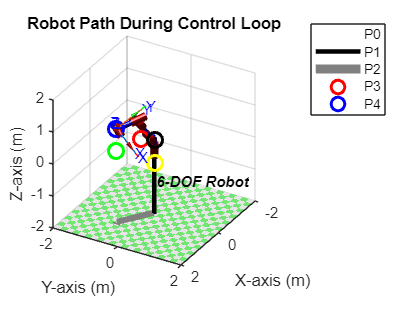

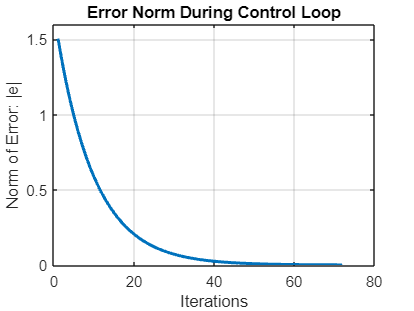

% Import the Robotics Toolbox

import robotics.*;

% Define the robot's DH parameters based on the provided table
L(1) = Revolute('d', 0, 'a', 0,     'alpha', pi);      % Joint virtual
L(2) = Revolute('d', -0.45, 'a', 0.15,     'alpha', pi/2);         % Joint 1
L(3) = Revolute('d', 0,     'a', 0.59, 'alpha', pi, 'offset', -pi/2); % Joint 2
L(4) = Revolute('d', 0,     'a', 0.13, 'alpha', -pi/2, 'offset', pi/2);  % Joint 3
L(5) = Revolute('d', -0.6471, 'a',0, 'alpha', -pi/2);    % Joint 4
L(6) = Revolute('d', 0,     'a', 0,     'alpha', pi/2);      % Joint 5
L(7) = Revolute('d', -0.095, 'a', 0,     'alpha', pi, 'offset', pi);      % Joint 6

% Combine the links into a SerialLink robot
robot = SerialLink(L, 'name', '6-DOF Robot');

% Display the robot's structure
robot.display();

q = [0, 0, 0, -90, 0, -90, 0]; % Define configuração inicial do robô

% Optional: Customize the workspace and viewing angle
robot.plotopt = {'workspace', [-2 2 -2 2 -2 2], 'view', [120, 30]};
robot.plot(q);

% Compute the Jacobian in the base frame
J = robot.jacob0(q);

% Display the Jacobian
disp('Jacobian Matrix (Base Frame):');
disp(J);

% Extrair apenas as 6 ultimas colunas (jacobiana reduzida para posição)
J_reduced = J(:, 2:7);

disp('Jacobiana Reduzida (para posição):');
disp(J_reduced);

 
%% Posições alvo (em mm convertidas para metros)
 P0 = [0.7; 0; 0.7];    % [700; 0; 700]
 P1 = [1; -0.6; 1]; % [1000; -600; 1000]
 P2 = [1; -0.6; 0.3]; % [1000; -600; 300]
 P3 = [1; 0.6; 0.3]; % [1000; 600; 300]
 P4 = [1; 0.6; 1]; % [1000; 600; 1000]

 % Matriz de rotação constante
Rd = [0  0  1;
     1  0  0;
     0 -1  0];

% Combinar posições e orientação em transformações homogêneas
T1 = [Rd, P1; 0 0 0 1];

i = 0;
hold on
% Plotar a posição (como ponto)
plot3(P0(1), P0(2), P0(3), 'ro', 'MarkerSize', 10, 'LineWidth', 2);
plot3(P1(1), P1(2), P1(3), 'ro', 'MarkerSize', 10, 'LineWidth', 2, 'Color', "blue");
plot3(P2(1), P2(2), P2(3), 'ro', 'MarkerSize', 10, 'LineWidth', 2, 'Color', "green");
plot3(P3(1), P3(2), P3(3), 'ro', 'MarkerSize', 10, 'LineWidth', 2, 'Color', "yellow");
plot3(P4(1), P4(2), P4(3), 'ro', 'MarkerSize', 10, 'LineWidth', 2, 'Color', "black");
% % Adicionar setas para orientação
% quiver3(P0(1), P0(2), P0(3), Rd(1,1), Rd(2,1), Rd(3,1), 0.1, 'r', 'LineWidth', 2, 'MaxHeadSize', 1); % Eixo X
% quiver3(P0(1), P0(2), P0(3), Rd(1,2), Rd(2,2), Rd(3,2), 0.1, 'g', 'LineWidth', 2, 'MaxHeadSize', 1); % Eixo Y
% quiver3(P0(1), P0(2), P0(3), Rd(1,3), Rd(2,3), Rd(3,3), 0.1, 'b', 'LineWidth', 2, 'MaxHeadSize', 1); % Eixo Z

% Resolver a cinemática inversa
q_solucao = robot.ikine(T1, q, [0, 1, 1, 1 ,1 ,1, 1]); % Ajuste as restrições conforme necessário
disp('Ângulos das juntas (cinemática inversa):');
disp(q_solucao);

T = robot.fkine(q_solucao) % Pega pose desejada do efetuador 
pd = transl(T); % Pega vetor de translação do efetuador
Rd = SO3(T); % Pega o objeto SO3 correspondente à rotação do efetuador
Rd = Rd.R(); %Pega matriz de rotação do efetuador

figure(1)
robot.plot(q); % Plot robô na configuração inicial
hold on
T.plot('rgb') % Plot pose desejada

% Inicialização
epsilon = 1e-5; % Critério de parada
K = 0.1; % Ganho proporcional
max_iterations = 1000; % Limite de iterações
i = 0;
e_ant = inf; % Inicializa erro anterior
e = zeros(6, 1); % Inicializa vetor de erro

% Loop de controle iterativo
while (norm(e - e_ant) > epsilon && i < max_iterations)
    i = i + 1;

    % Cinemática direta
    T = robot.fkine(q);
    p = transl(T);
    R = SO3(T).R(); % Matriz de rotação atual

    % Erros
    p_err = pd - p; % Erro de posição
    nphi = rotm2axang2(Rd * R'); % Erro de rotação no formato eixo-ângulo
    nphi_err = nphi(1:3) * nphi(4);

    e_ant = e;
    e = [p_err, nphi_err];

   % Controle
    u = pinv(J_reduced) * K * e'; % Lei de controle
    q(2:7) = q(2:7) + 0.1 * u'; % Atualiza somente as juntas móveis

    % Visualização
    robot.plot(q); pause(0.1);
    control_sig(:, i) = u; % Armazena sinal de controle
    err(i) = norm(e); % Norma do erro
end
hold off

% Plot sinal de controle e norma do erro

figure(2)
hold on
for i = 1:6
    plot(control_sig(i,:))
end
hold off
xlabel('Iterações')
ylabel('Sinal de controle: u(rad/s)')

figure(3)
plot(err)
xlabel('Iterações')
ylabel('Norma do erro: |e|')
box off

% Optional: Customize the workspace and viewing angle
c = [0 1.5708 0 -1.5708 0 -1.5708 1.5708]';
robot.plotopt = {'workspace', [-2 2 -2 2 -2 2], 'view', [120, 30]};
robot.plot(c);
